# Creation of a small GUI to show sensor data

By Johannes Sutter and Adei Garmendia Garcia

23.11.2024

Initial Setup

clear;
clc;
close all;
cd(fileparts(matlab.desktop.editor.getActiveFilename))

Generation of static sensor values

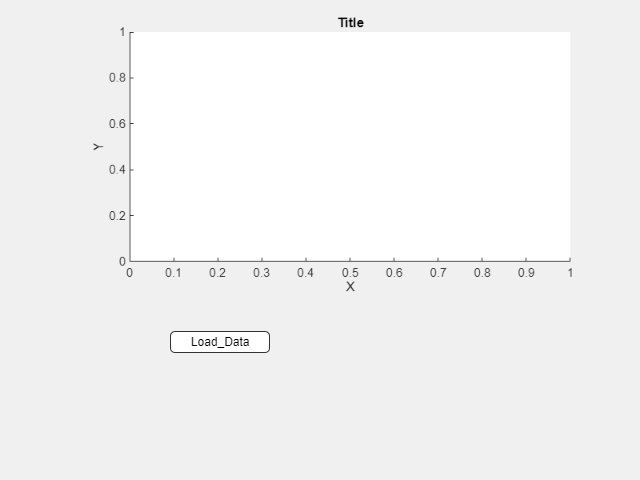

sensorData = 0:1:100;
sensorTime = 0:0.02:2;
run('Show_sensor_data.mlapp');

Generation of dynamic, random sensor values

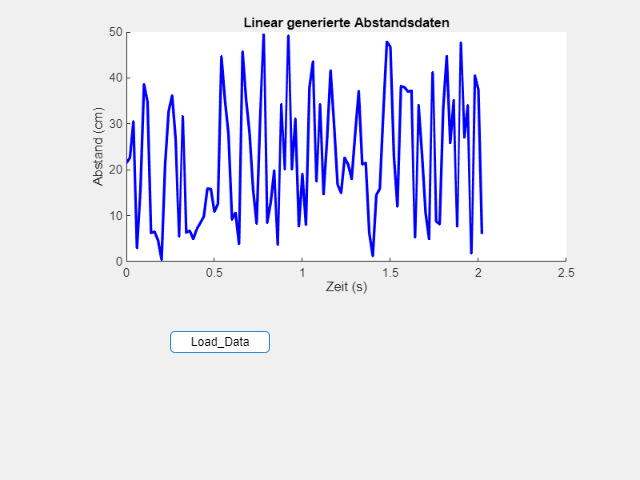

run('Show_sensor_data.mlapp');

T = timer('TimerFcn',@(~,~)disp('Fired.'),'StartDelay',0.02);
i=6;
k=1;
sensorTime(k)=0;
sensorData(k) = 50 * rand(1, 1);
while i>1
    k=k+1;
    sensorData(k) = 50 * rand(1, 1);
    sensorTime(k) = 0.02+sensorTime(k-1);
    assignin('base', 'sensorData', sensorData);
    assignin('base', 'sensorTime', sensorTime);
    start(T)
    wait(T)
end

Open the matlab inbuilt example

openExample('matlab/AppdMemoryMonitorExample');